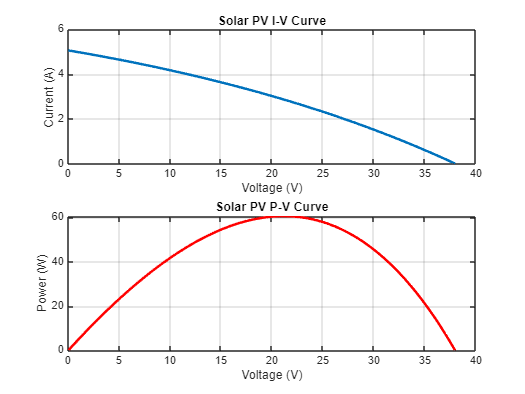

clc; clear; close all;

%% --- PV Module Parameters ---
Isc = 8;        % Short-circuit current (A)
Voc = 38;       % Open-circuit voltage (V)
Ns = 36;        % Number of series cells
G = 1000;       % Irradiance (W/m^2)
T = 25 + 273;   % Temperature in Kelvin

%% --- Generate PV I-V Characteristics ---
V = linspace(0, Voc, 200);
I = Isc * (1 - exp((V - Voc)/Voc));   % Simple PV approximation

P = V .* I;      % Power curve

%% --- Plot I-V and P-V curves ---
figure;
subplot(2,1,1);
plot(V, I, 'LineWidth', 2); grid on;
xlabel('Voltage (V)'); ylabel('Current (A)');
title('Solar PV I-V Curve');

subplot(2,1,2);
plot(V, P, 'r', 'LineWidth', 2); grid on;
xlabel('Voltage (V)'); ylabel('Power (W)');
title('Solar PV P-V Curve');

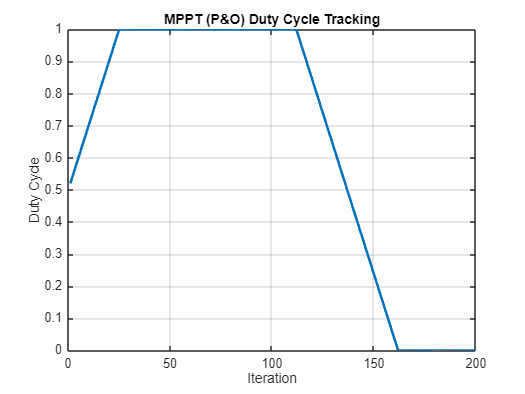


%% --- MPPT Using Perturb & Observe (P&O) ---
Vpv = 0;                 % Initial voltage
D = 0.5;                 % Initial duty cycle
step = 0.02;             % Perturbation step
prevP = 0;
prevV = 0;
N = length(V);

D_values = zeros(1, N);
P_values = zeros(1, N);

for k = 1:N
    Vpv = V(k);
    Ipv = I(k);
    Ppv = Vpv * Ipv;

    if Ppv > prevP
        if Vpv > prevV
            D = D + step;   % move right
        else
            D = D - step;   % move left
        end
    else
        if Vpv > prevV
            D = D - step;
        else
            D = D + step;
        end
    end

    prevP = Ppv;
    prevV = Vpv;

    D = min(max(D, 0), 1);   % limit duty cycle
    D_values(k) = D;
    P_values(k) = Ppv;
end

%% --- Plot MPPT Tracking ---
figure;
plot(D_values, 'LineWidth', 2);
grid on; xlabel('Iteration'); ylabel('Duty Cycle');
title('MPPT (P&O) Duty Cycle Tracking');

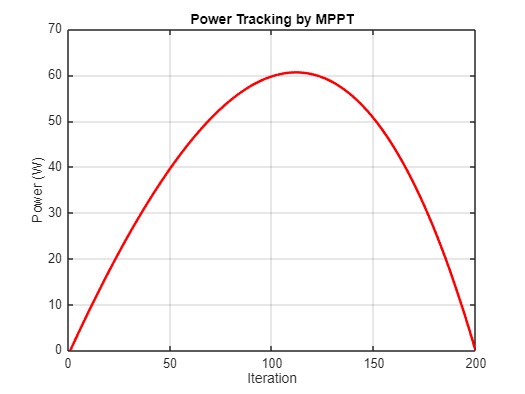


figure;
plot(P_values, 'r', 'LineWidth', 2);
grid on; xlabel('Iteration'); ylabel('Power (W)');
title('Power Tracking by MPPT');